# Comandos Scilab

Nesta seção, são abordados alguns problemas associados a Sistemas de Controle. Considera-se a configuração padrão do sistema realimentado da Fig. 01.

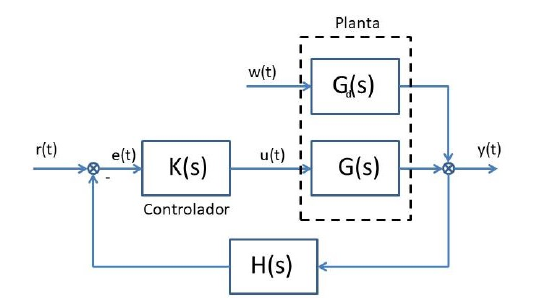

## PROBLEMAS:

Seja o sistema de controle da Fig. 01 com as funções de transferência dadas a seguir e $G_d(s) = 0$:


$$$$G(s)=\frac{s^2 + s + 2}{s(s + 5)(s^2 + 2s + 1)}$$ $$H(s)=1$$ $$K(s)=\frac{20s + 0.01}{s}$$$$


- 1) Obter a função de transferência de malha-fechada resultante; 

- 2) Calcular uma representação no espaço de estados para a planta, O controlador e o sistema em malha-fechada; 

- 3) Analisar a estabilidade do sistema em malha-fechada utilizando a função de transferência e o modelo no espaço de estados. Encontrar o polinômio caracterı́stico do sistema resultante;

- 4) Obter os sinais de saı́da y(t) e controle u(t) do sistema em malha fechada para a entrada r(t) o degrau unitário e o impulso unitário. Determinar o maior pico do sinal de saı́da e o tempo que a saı́da leva para atingir 98% do regime permanente, para r(t) = 1; 

- 5) Calcular a saı́da do sistema em malha-fechada para as entradas r(t) = sen(πt) e r(t) uma onda quadrada de amplitude unitária e perı́odo igual a quatro; 

- 6) Analisar a controlabilidade e a observabilidade da planta a ser controlada (G(s)) e obter a forma de Jordan associada à matriz dinâmica (planta);

- 7) Com $G_d(s) =\frac{1}{s^2 +s+1}$ , obter a resposta em frequência entre a saı́da y e a perturbaçaõ w ; 

- 8) O controlador K(s) é substituı́do pelo controlador digital $K(z)$ com o segurador de ordem zero (ZOH), conforme a Fig. 02. Obter o modelo discreto para a planta e ZOH (visto pelo controlador) e, em seguida, calcular a função de transferência discreta de malha-fechada. Calcular a resposta ao degrau unitário e analisar a estabilidade do sistema resultante de malha-fechada. O perı́odo de amostragem é $T_s = 0.01s$ e $K(z) = \frac{0.473z - 0.4728}{z-1}$

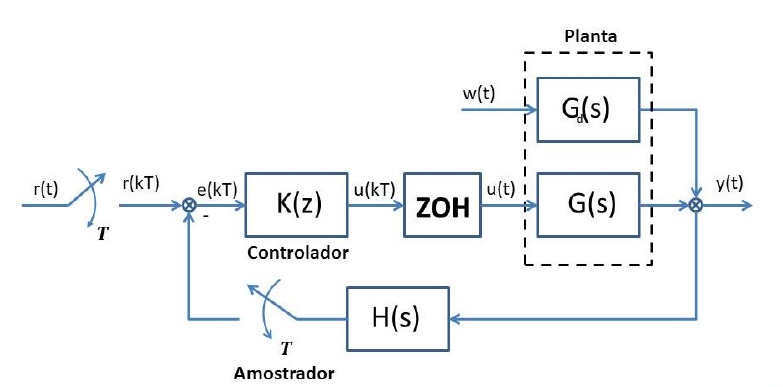

### Problema 1:

Obter a função de transferência de malha-fechada resultante.

Primeiro vamos determinar G(s):

num = [1 1 2]; 
den = conv([1,5,0],[1,2,1]); 
G = tf(num,den)

G =
 
         s^2 + s + 2
  --------------------------
  s^4 + 7 s^3 + 11 s^2 + 5 s
 
Continuous-time transfer function.



Agora o H(s):

H = tf(1,1)

H =
 
  1
 
Static gain.



E por fim o K(s)

K = tf([20 0.01],[1 0])

K =
 
  20 s + 0.01
  -----------
       s
 
Continuous-time transfer function.



Vamos agora obter a função transferência equivalente do bloco G e K em série:

FS = series(G,K)

FS =
 
  20 s^3 + 20.01 s^2 + 40.01 s + 0.02
  -----------------------------------
     s^5 + 7 s^4 + 11 s^3 + 5 s^2
 
Continuous-time transfer function.



Por conta da realimentação, a equação que define o circuito da malha fechada é $\frac{GK}{1+GK}$

MF = feedback(FS,H,-1)

MF =
 
         20 s^3 + 20.01 s^2 + 40.01 s + 0.02
  -------------------------------------------------
  s^5 + 7 s^4 + 31 s^3 + 25.01 s^2 + 40.01 s + 0.02
 
Continuous-time transfer function.



Para obter o numerador e o denominador da função transferência de malha fechada:

[num_mf,den_mf] = tfdata(MF)

num_mf = 1×1 cell array
    {[0 0 20 20.0100 40.0100 0.0200]}


den_mf = 1×1 cell array
    {[1 7 31 25.0100 40.0100 0.0200]}


Agora este objeto é guardado em forma de célula, para isso, deve ser convertido para matriz:

num_mf = cell2mat(num_mf)

num_mf =          0         0   20.0000   20.0100   40.0100    0.0200


den_mf = cell2mat(den_mf)

den_mf =     1.0000    7.0000   31.0000   25.0100   40.0100    0.0200


Para saber as raízes, podemos usar a função `roots:`

roots(num_mf)

ans =   -0.5000 + 1.3229i
  -0.5000 - 1.3229i
  -0.0005 + 0.0000i


roots(den_mf)

ans =   -3.2077 + 3.9247i
  -3.2077 - 3.9247i
  -0.2921 + 1.2130i
  -0.2921 - 1.2130i
  -0.0005 + 0.0000i


Uma função útil para ver os pólos e zeros:

zpk(MF)

ans =
 
                 20 (s+0.0005) (s^2 + s + 2)
  ---------------------------------------------------------
  (s+0.0005) (s^2 + 0.5841s + 1.557) (s^2 + 6.415s + 25.69)
 
Continuous-time zero/pole/gain model.



## Problema 2

Calcular uma representação no espaço de estados para a planta, O controlador e o sistema em malha-fechada

Para G(s):

[A,B,C,D]=tf2ss(num,den)

A =     -7   -11    -5     0
     1     0     0     0
     0     1     0     0
     0     0     1     0


B =      1
     0
     0
     0


C =      0     1     1     2


D = 0

Para K(s)

[Ak,Bk,Ck,Dk]=tf2ss([20 0.01],[1 0])

Ak = 0

Bk = 1

Ck = 0.0100

Dk = 20

H(s):

[Ah,Bh,Ch,Dh]=tf2ss(1,1)


Ah =

     []


Bh =

     []


Ch =

     []



Dh = 1

Agora podemos criar o modelo de espaço de estados:

ssG = ss(A,B,C,D)

ssG =
 
  A = 
        x1   x2   x3   x4
   x1   -7  -11   -5    0
   x2    1    0    0    0
   x3    0    1    0    0
   x4    0    0    1    0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   1   2
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Para se obter as informações desse objeto, podemos fazer:

get(ssG)

                A: [4×4 double]
                B: [4×1 double]
                C: [0 1 1 2]
                D: 0
                E: []
           Scaled: 0
        StateName: {4×1 cell}
        StatePath: {4×1 cell}
        StateUnit: {4×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
               Ts: 0
         TimeUnit: 'seconds'
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]



Para obter algum atributo do objeto, como por exemplo a matriz A, podemos fazer:

ssG.A

ans =     -7   -11    -5     0
     1     0     0     0
     0     1     0     0
     0     0     1     0


Para K(s):

ssK = ss(Ak, Bk, Ck, Dk)

ssK =
 
  A = 
       x1
   x1   0
 
  B = 
       u1
   x1   1
 
  C = 
         x1
   y1  0.01
 
  D = 
       u1
   y1  20
 
Continuous-time state-space model.



Podemos usar o comando `series` no espaço de estados também:

ssGK = series(ssG,ssK)

ssGK =
 
  A = 
        x1   x2   x3   x4   x5
   x1    0    0    1    1    2
   x2    0   -7  -11   -5    0
   x3    0    1    0    0    0
   x4    0    0    1    0    0
   x5    0    0    0    1    0
 
  B = 
       u1
   x1   0
   x2   1
   x3   0
   x4   0
   x5   0
 
  C = 
         x1    x2    x3    x4    x5
   y1  0.01     0    20    20    40
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



E podemos também usar a função `feedback`:

ssMF = feedback(ssGK,1)

ssMF =
 
  A = 
          x1     x2     x3     x4     x5
   x1      0      0      1      1      2
   x2  -0.01     -7    -31    -25    -40
   x3      0      1      0      0      0
   x4      0      0      1      0      0
   x5      0      0      0      1      0
 
  B = 
       u1
   x1   0
   x2   1
   x3   0
   x4   0
   x5   0
 
  C = 
         x1    x2    x3    x4    x5
   y1  0.01     0    20    20    40
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



E para extrair os dados:

[Amf,Bmf,Cmf,Dmf] = ssdata(ssMF)

Amf =          0         0    1.0000    1.0000    2.0000
   -0.0100   -7.0000  -31.0000  -25.0000  -40.0000
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0


Bmf =      0
     1
     0
     0
     0


Cmf =     0.0100         0   20.0000   20.0000   40.0000


Dmf = 0

Para obter mais informações:

get(ssMF)

                A: [5×5 double]
                B: [5×1 double]
                C: [0.0100 0 20 20 40]
                D: 0
                E: []
           Scaled: 0
        StateName: {5×1 cell}
        StatePath: {5×1 cell}
        StateUnit: {5×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
               Ts: 0
         TimeUnit: 'seconds'
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]



E para encontrar os pólos e zeros (e já obter a função transferência):

zpk(ssMF)

ans =
 
                 20 (s+0.0005) (s^2 + s + 2)
  ---------------------------------------------------------
  (s+0.0005) (s^2 + 0.5841s + 1.557) (s^2 + 6.415s + 25.69)
 
Continuous-time zero/pole/gain model.



Para só ir para função transferência:

tf(ssMF)

ans =
 
         20 s^3 + 20.01 s^2 + 40.01 s + 0.02
  -------------------------------------------------
  s^5 + 7 s^4 + 31 s^3 + 25.01 s^2 + 40.01 s + 0.02
 
Continuous-time transfer function.



### Problema 3

Analisar a estabilidade do sistema em malha-fechada utilizando a função de transferência e o modelo no espaço de estados. Encontrar o polinômio caracterı́stico do sistema resultante;

Para isso, iremos olhar as raízes do denominador e ver que todos estão no semiplano esquerdo.

roots(den_mf)

ans =   -3.2077 + 3.9247i
  -3.2077 - 3.9247i
  -0.2921 + 1.2130i
  -0.2921 - 1.2130i
  -0.0005 + 0.0000i


Para olhar os autovalores:

eig(Amf)

ans =   -3.2077 + 3.9247i
  -3.2077 - 3.9247i
  -0.2921 + 1.2130i
  -0.2921 - 1.2130i
  -0.0005 + 0.0000i


Esta função, pode retornar autovalores e autovetores.

[p,v]=eig(Amf)

p =   -0.0037 + 0.0327i  -0.0037 - 0.0327i  -0.1597 - 0.0093i  -0.1597 + 0.0093i   1.0000 + 0.0000i
   0.9798 + 0.0000i   0.9798 + 0.0000i  -0.6481 + 0.0000i  -0.6481 + 0.0000i   0.0000 + 0.0000i
  -0.1223 - 0.1497i  -0.1223 + 0.1497i   0.1216 + 0.5050i   0.1216 - 0.5050i  -0.0000 + 0.0000i
  -0.0076 + 0.0374i  -0.0076 - 0.0374i   0.3707 - 0.1895i   0.3707 + 0.1895i   0.0000 + 0.0000i
   0.0067 - 0.0035i   0.0067 + 0.0035i  -0.2172 - 0.2533i  -0.2172 + 0.2533i  -0.0003 + 0.0000i


v =   -3.2077 + 3.9247i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -3.2077 - 3.9247i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2921 + 1.2130i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2921 - 1.2130i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0005 + 0.0000i


Podemos gerar também uma matriz de forma aleatória, e usar com a `eig`:

J=rand(3,3)

J =     0.0938    0.8611    0.6714
    0.5254    0.4849    0.7413
    0.5303    0.3935    0.5201


[p2,v2]=eig(J)

p2 =    -0.5876   -0.8817   -0.5247
   -0.6224    0.1499   -0.4450
   -0.5170    0.4474    0.7257


v2 =     1.5966         0         0
         0   -0.3933         0
         0         0   -0.1046


Para encontrar o polinômio característico:

poly(Amf)

ans =     1.0000    7.0000   31.0000   25.0100   40.0100    0.0200


Para encontrar os polos e zeros, diretamente da função transferência:

pole(MF)

ans =   -3.2077 + 3.9247i
  -3.2077 - 3.9247i
  -0.2921 + 1.2130i
  -0.2921 - 1.2130i
  -0.0005 + 0.0000i


zero(MF)

ans =   -0.5000 + 1.3229i
  -0.5000 - 1.3229i
  -0.0005 + 0.0000i


Isso também pode ser feito diretamente da representação de espaço de estados:

pole(ssMF)

ans =   -3.2077 + 3.9247i
  -3.2077 - 3.9247i
  -0.2921 + 1.2130i
  -0.2921 - 1.2130i
  -0.0005 + 0.0000i


zero(ssMF)

ans =   -0.0005 + 0.0000i
  -0.5000 + 1.3229i
  -0.5000 - 1.3229i


Para verificar estabilidade da função transferência:

isstable(MF)

ans = logical
   1


Para verificar estabilidade no espaço de estados:

isstable(ssMF)

ans = logical
   1


Para ver o mapa de pólos e zeros:

[polos,zeros]=pzmap(MF) % Funciona com um objeto ss, tf ou zpk

polos =   -3.2077 + 3.9247i
  -3.2077 - 3.9247i
  -0.2921 + 1.2130i
  -0.2921 - 1.2130i
  -0.0005 + 0.0000i


zeros =   -0.5000 + 1.3229i
  -0.5000 - 1.3229i
  -0.0005 + 0.0000i


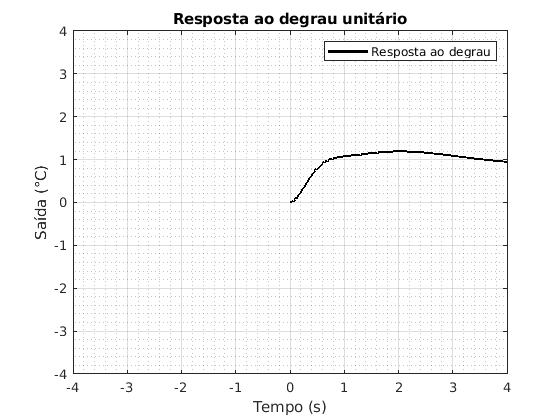

axis([-4 4 -4 4])
grid

#### Análise com Lyapunov

Para ver o que a função faz:

help lyap

 lyap  Solve continuous-time Lyapunov equations.
 
    X = lyap(A,Q) solves the Lyapunov matrix equation:
 
        A*X + X*A' + Q = 0
 
    X = lyap(A,B,C) solves the Sylvester equation:
 
        A*X + X*B + C = 0
 
    X = lyap(A,Q,[],E) solves the generalized Lyapunov equation:
 
        A*X*E' + E*X*A' + Q = 0    where Q is symmetric
 
    See also lyapchol, dlyap.

    Documentation for lyap



Iremos usar a primeira opção do comando acima, para isso, definiremos uma matriz Q diagonal positiva qualquer e obteremos os autovetores e autovalores da matriz W, solução da equação de Lyapunov

Q = eye(5);
W = lyap(Amf,Q)

W = 	1.0e+03 *

    1.4907    0.0014   -0.0011   -0.0012    0.0009
    0.0014    0.0152   -0.0005   -0.0044    0.0005
   -0.0011   -0.0005    0.0044   -0.0005   -0.0026
   -0.0012   -0.0044   -0.0005    0.0026   -0.0005
    0.0009    0.0005   -0.0026   -0.0005    0.0022


[V,D] = eig(W)

V =     0.0002   -0.0005   -0.0009    0.0012   -1.0000
    0.1266   -0.2777   -0.0342   -0.9517   -0.0009
    0.5058    0.2053   -0.8370    0.0374    0.0008
    0.4577   -0.8323    0.0859    0.3007    0.0008
    0.7201    0.4336    0.5393   -0.0501   -0.0006


D = 	1.0e+03 *

    0.0001         0         0         0         0
         0    0.0015         0         0         0
         0         0    0.0061         0         0
         0         0         0    0.0166         0
         0         0         0         0    1.4908


Para obter a diagonal em um vetor da matriz diagonal:

diag(D) % A função também cria uma matriz diagonal

ans = 	1.0e+03 *

    0.0001
    0.0015
    0.0061
    0.0166
    1.4908


E para obter o determinante da matriz:

det(W)

ans = 1.7862e+04

### Problema 4

Obter os sinais de saı́da y(t) e controle u(t) do sistema em malha fechada para a entrada r(t) o degrau unitário e o impulso unitário. Determinar o maior pico do sinal de saı́da e o tempo que a saı́da leva para atingir 98% do regime permanente, para r(t) = 1.

Podemos usar a função `step`:

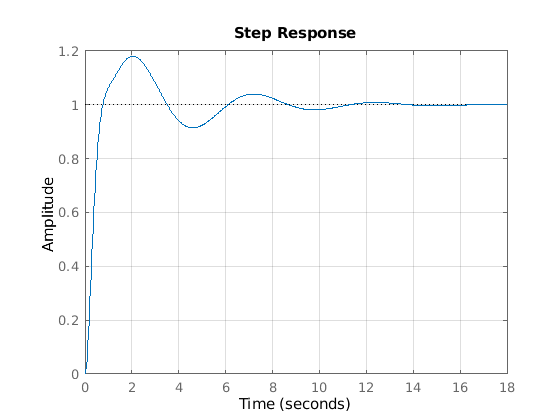

step(MF)
grid

Para fazer o seu próprio gráfico:

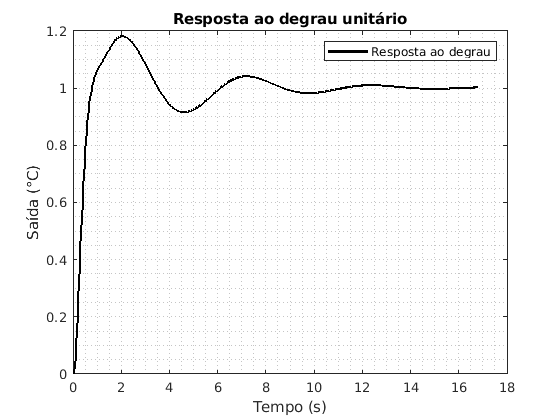

[y, t] = step(MF);
plot(t,y,'k-','LineWidth',2); grid minor;
title('Resposta ao degrau unitário');
xlabel('Tempo (s)'); ylabel('Saída (°C)'); legend('Resposta ao degrau');

Para obter o valor máximo da saída:

tempMax = max(y)

tempMax = 1.1807

E para obter o tempo em que isso ocorre:

[vv,pp] = max(y);
tempo98 = t(pp)

tempo98 = 2.0386

Para obter o U(s):

U = K/(1+FS)

U =
 
   20 s^6 + 140 s^5 + 220.1 s^4 + 100.1 s^3 + 0.05 s^2
  -----------------------------------------------------
  s^6 + 7 s^5 + 31 s^4 + 25.01 s^3 + 40.01 s^2 + 0.02 s
 
Continuous-time transfer function.



Agora, vamos plotar o gráfico:

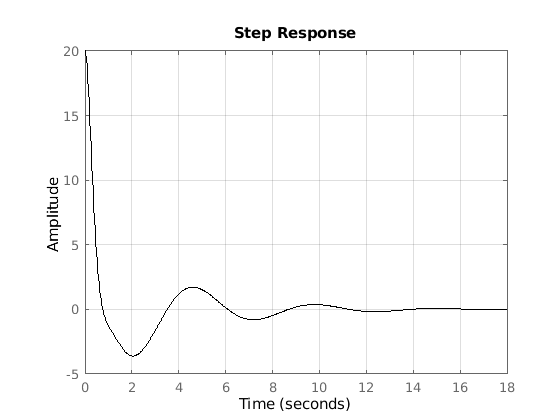

step(U,'k'); grid;